## Import Menzies Data

clear;
data = readtable("data.xlsx");

DCData = readtable("OnlineData\Commercial-Middle School.csv");


% Specify the number of elements to wrap around (e.g., the middle portion)
numElementsToWrap = 8760-(24*7+24*7*30); % Adjust as needed

% Determine the size of the data vector
numTotalElements = size(DCData(:,1));

% Shift the middle portion to the beginning and wrap it
startIndex = numTotalElements - numElementsToWrap + 1;
DCDataWrapped = vertcat(DCData(startIndex:end,"Power_kW_"), DCData(1:startIndex - 1,"Power_kW_"));

% Display the result

data = horzcat(data,DCDataWrapped);

data = renamevars(data, "Power_kW_","DC")

data = 8760×26 table
    meter_serial            meter_desc                   tstamp              date            day           time          tou         week_number            impwh             difference_imp_kwh     ptot      stot     expwh    difference_exp_kwh    pftot      md       qtot      epoch_timestamp        interval_start       waste    meter_id    tou_id    season_profile_id    season_class_id    tariff_id     DC 
    ____________    __________________________    ____________________    <s

%Remove data with no information  
data = removevars(data, ["meter_serial", "tstamp","meter_desc", "expwh","difference_exp_kwh","interval_start", "waste", "meter_id", "tariff_id","tou", "impwh","stot", "pftot","md","qtot","difference_imp_kwh"]);

%data.impwh = erase(data.impwh,',');
data.epoch_timestamp = erase(data.epoch_timestamp, ',');
data.epoch_timestamp = str2double(data.epoch_timestamp);


data.day =  day(data.date, "dayofweek");
data.date = day(data.date, "dayofyear");

data.day =data.day-1;

for i = 1:size(data.day(:))
    if (data.day(i) ==0)
        data.day(i) =7;
    end
end

data.month = month(data.date);

low_time = 0.29; % 7am
up_time = 0.75; %  6pm

wrkHrsCondition = (data.time >= low_time) & (data.time <= up_time) & (data.day ~= 6) & (data.day ~= 7);
dayTimeCondition =  (data.time >= low_time) & (data.time <= up_time);
weekDayCondition = (data.day ~= 6) & (data.day ~= 7) ;

data.wrkHr      = wrkHrsCondition;

data.dayTime    =  dayTimeCondition;

data.weekDay    = weekDayCondition;



% tou make hot one var because of nominal value
% same shit for day of week
% 


Cleaning data

- MCAR (Missing completely at random): These are values that are randomly missing and do not depend on any other values.

- MAR (Missing at random): These values are dependent on some additional features.

- MNAR (Missing not at random): There is a reason behind why these values are missing.

I have used fill with Previous because there are only 6 rows and I want to keep the time series intact.

missingElements = ismissing(data, {string(missing),NaN});
rowsWithMissing = any(missingElements, 2);

missingValuesTable = data(rowsWithMissing,:);


% Fill missing data
[data,missingIndices] = fillmissing(data,"previous");

data 

data = 8760×14 table
    date    day      time      week_number     ptot     epoch_timestamp    tou_id    season_profile_id    season_class_id     DC     month    wrkHr    dayTime    weekDay
    ____    ___    ________    ___________    ______    _______________    ______    _________________    _______________    ____    _____    _____    _______    _______

     1       6            0         1         96.855       1.641e+09         3              72                   3           52.2      1      false     false     

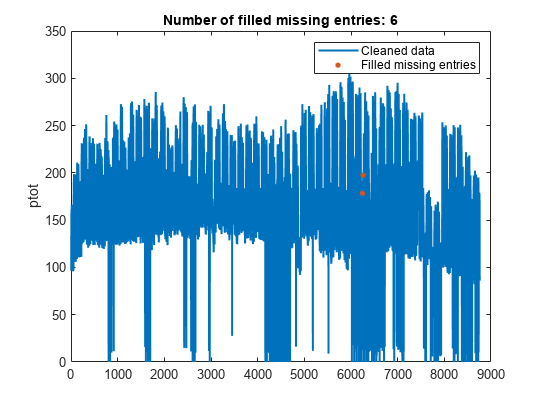


% Display results
figure

% Plot cleaned data
plot(data.ptot,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Cleaned data")
hold on

% Plot filled missing entries
plot(find(missingIndices(:,5)),data.ptot(missingIndices(:,5)),".",...
    "MarkerSize",12,"Color",[217 83 25]/255,...
    "DisplayName","Filled missing entries")
title("Number of filled missing entries: " + nnz(missingIndices(:,5)))

hold off
legend
ylabel("ptot")

clear missingIndices


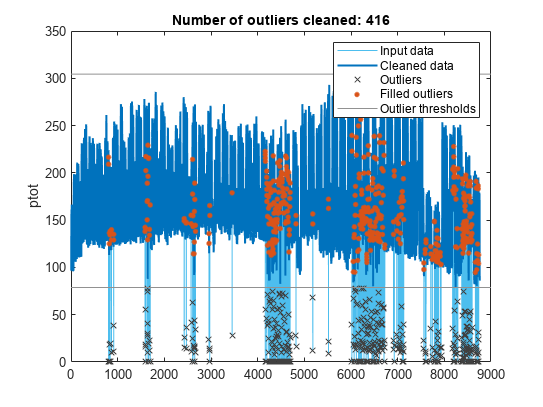



% Fill outliers
[dataTest1,outlierIndices5,thresholdLow5,thresholdHigh5] = filloutliers(data,...
    "linear","percentiles",[4.75 100],"DataVariables","ptot");

% Display results
figure
plot(data.ptot,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(dataTest1.ptot,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Cleaned data")

% Plot outliers
plot(find(outlierIndices5(:,5)),data.ptot(outlierIndices5(:,5)),"x",...
    "Color",[64 64 64]/255,"DisplayName","Outliers")

% Plot filled outliers
plot(find(outlierIndices5(:,5)),dataTest1.ptot(outlierIndices5(:,5)),".",...
    "MarkerSize",12,"Color",[217 83 25]/255,"DisplayName","Filled outliers")

% Plot outlier thresholds
plot([xlim missing xlim],[thresholdLow5.ptot*[1 1] NaN thresholdHigh5.ptot*[1 1]],...
    "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

hold off
title("Number of outliers cleaned: " + nnz(outlierIndices5(:,5)))
legend
ylabel("ptot")

clear thresholdLow5 thresholdHigh5


data = dataTest1;

%write to a table
writetable(data(:,"ptot"),'ACload.csv',"Delimiter",',');
writetable(data(:,"DC"), 'DCload.csv', "Delimiter", ',');

Adding in futValues

%futPtot = array2table(data.ptot(25:end),"VariableNames","futPtot");
%data = horzcat(data(1:end-24,:), futPtot)


[`N`](https://www.mathworks.com/help/matlab/ref/double.normalize.html#mw_9405678c-6c76-491a-83e4-b928ee0b5cee) `= normalize(`[`A`](https://www.mathworks.com/help/matlab/ref/double.normalize.html#d124e1045357)`)` returns the vectorwise [*z*-score](https://www.mathworks.com/help/matlab/ref/double.normalize.html#mw_e6886c44-2923-4074-844a-f3e1a447359d) of the data in `A` with center 0 and standard deviation 1.

- If `A` is a table or timetable, then `normalize` operates on each variable of `A` separately.

%data = normalize(data);


my normal 

Xhat = (X-Xmin)/(Xmax-Xmix)

summary(data)

Variables:

    date: 8760×1 double

        Values:

            Min           1   
            Median      183   
            Max         365   

    day: 8760×1 double

        Values:

            Min          1    
            Median       4    
            Max          7    

    time: 8760×1 double

        Values:

            Min             0 
            Median    0.47917 
            Max       0.95833 

    week_number: 8760×1 double

        Values:

            Min           1   
            Median       27   
            Max          53   

    ptot: 8760×1 double

        Values:

            Min         79.12 
            Median     165.23 
            Max        304.46 

    epoch_timestamp: 8760×1 double

        Values:

            Min        1.641e+09
            Median    1.6568e+09
            Max       1.6725e+09

    tou_id: 8760×1 double

   

Stratification of data

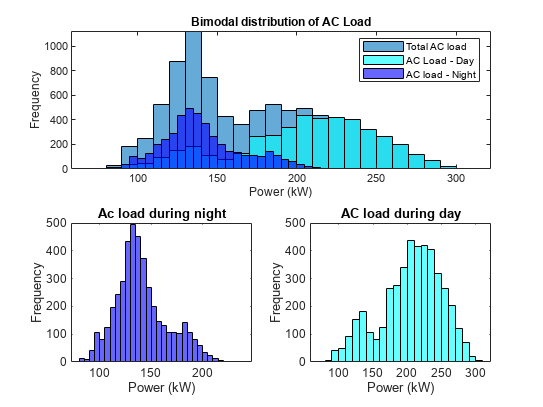

ptotWrkHrs = data.ptot(data.wrkHr==true);
ptotNotWrkHrs = data.ptot(data.wrkHr == false);

ptotDayTime = data.ptot(data.dayTime == true);
ptotNotDayTime = data.ptot(data.dayTime == false);

ptotWeek  = data.ptot(data.weekDay == true);
ptotNotWeek= data.ptot(data.weekDay == false);


ptotWeekendNight = data.ptot(data.weekDay == false & data.dayTime == false);
ptotWeekendDay = data.ptot(data.weekDay == false & data.dayTime == true);

ptotSaturday  = data.ptot(data.day == 6 & data.dayTime == true);
ptotSunday    = data.ptot(data.day == 7 & data.dayTime  == true);

figure
subplot(2,2,[1 2])
histogram(data.ptot )
hold on
histogram(ptotDayTime, "FaceColor","c")
histogram(ptotNotDayTime, "FaceColor","b")
hold off
legend("Total AC load", "AC Load - Day", "AC load - Night")
title("Bimodal distribution of AC Load")
xlabel("Power (kW)")
ylabel("Frequency");

subplot(2,2,3)
histogram(ptotNotDayTime, "FaceColor","b")
title("Ac load during night")
xlabel("Power (kW)")
ylabel("Frequency");
subplot(2,2,4)
histogram(ptotDayTime, "FaceColor","c")
title("AC load during day")
xlabel("Power (kW)")
ylabel("Frequency");

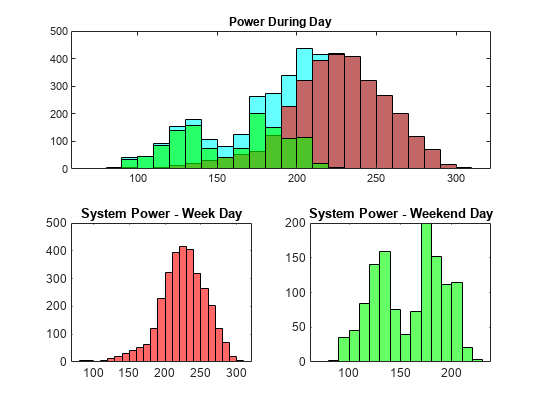


figure
subplot(2,2,[1 2])
histogram(ptotDayTime, "FaceColor","c")
hold on
histogram(ptotWrkHrs, "FaceColor","r")
histogram(ptotWeekendDay, "FaceColor","g")
hold off
title("Power During Day")
subplot(2,2,3)
histogram(ptotWrkHrs,"FaceColor","r")
title("System Power - Week Day")
subplot(2,2,4)
histogram(ptotWeekendDay, "FaceColor","g")
title("System Power - Weekend Day")

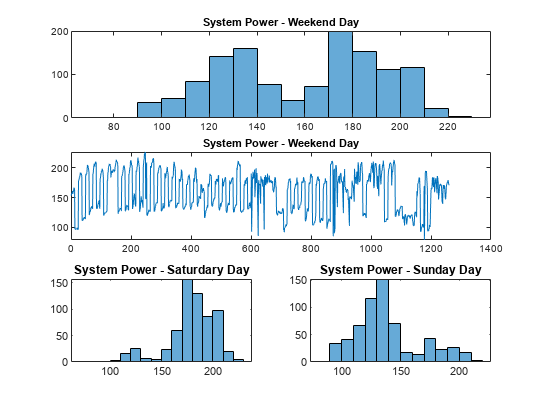


figure
subplot(3,2,[1 2])
histogram(ptotWeekendDay)
title("System Power - Weekend Day")
subplot(3,2,[3 4])
plot(ptotWeekendDay)
title("System Power - Weekend Day")
subplot(3,2,5)
histogram(ptotSaturday)
title("System Power - Saturdary Day")
subplot(3,2,6)
histogram(ptotSunday)
title("System Power - Sunday Day")

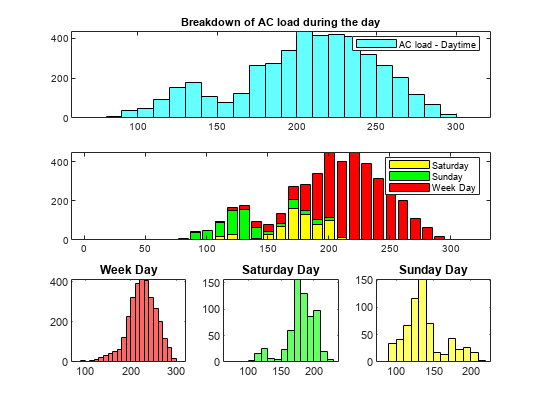




% figure
% histogram(ptotDayTime,"FaceColor","c")
% hold on 
% histogram(ptotWrkHrs, "FaceColor","r")
% histogram(ptotSaturday,"FaceColor","g")
% histogram(ptotSunday, "FaceColor", "y")
% hold off
% legend("Day Power", "Week Day", "Saturday","Sunday")

figure 
binrng = 1:10:330;
constDayTime = histc(ptotDayTime,binrng);
constWrkHrs  = histc(ptotWrkHrs,binrng);
constSat     = histc(ptotSaturday,binrng);
constSun     = histc(ptotSunday,binrng);
dayBreakDown = [constSat,constSun,constWrkHrs];

subplot(3,3,[1 2 3])
histogram(ptotDayTime, "FaceColor","c")
title("Breakdown of AC load during the day")
legend("AC load - Daytime")

subplot(3,3,[4 5 6])
b = bar(binrng, dayBreakDown,"stacked");
b(3).FaceColor = "red";
b(2).FaceColor = "green";
b(1).FaceColor = "y";
legend( "Saturday","Sunday","Week Day")

subplot(3,3,7)
histogram(ptotWrkHrs, "FaceColor","r")
title("Week Day")
subplot(3,3,8)
histogram(ptotSaturday, "FaceColor","g")
title("Saturday Day")
subplot(3,3,9)
histogram(ptotSunday, "FaceColor","y")
title("Sunday Day")



% bar(binrng, constDayTime, "b")
% hold on
% bar(binrng, constWrkHrs, "r")
% bar(binrng, constSat, "g")
% bar(binrng, constSun, "c")
% hold off


% figure
% subplot(2,2,[1 2])
% histogram(ptotNotWeek)
% title("System Power during Weekend")
% subplot(2,2,3)
% histogram(ptotWeekendNight)
% title("System Power - Weekend Night")
% subplot(2,2,4)
% histogram(ptotWeekendDay)
% title("System Power - Weekend Day")

DC Daily Load Stratification

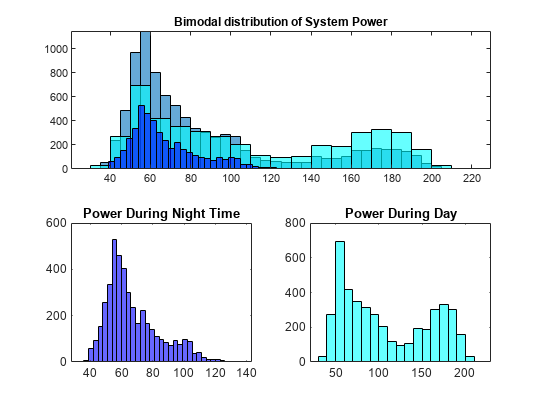

DCWrkHrs = data.DC(data.wrkHr==true);
DCNotWrkHrs = data.DC(data.wrkHr == false);

DCDayTime = data.DC(data.dayTime == true);
DCNotDayTime = data.DC(data.dayTime == false);

DCWeek  = data.DC(data.weekDay == true);
DCNotWeek= data.DC(data.weekDay == false);


DCWeekendNight = data.DC(data.weekDay == false & data.dayTime == false);
DCWeekendDay = data.DC(data.weekDay == false & data.dayTime == true);

DCSaturday  = data.DC(data.day == 6 & data.dayTime == true);
DCSunday    = data.DC(data.day == 7 & data.dayTime  == true);

figure
subplot(2,2,[1 2])
histogram(data.DC )
hold on
histogram(DCDayTime, "FaceColor","c")
histogram(DCNotDayTime, "FaceColor","b")
hold off
title("Bimodal distribution of System Power")

subplot(2,2,3)
histogram(DCNotDayTime, "FaceColor","b")
title("Power During Night Time")
subplot(2,2,4)
histogram(DCDayTime, "FaceColor","c")
title("Power During Day")

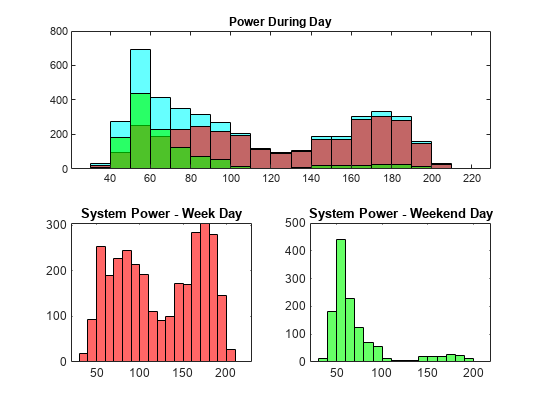



figure
subplot(2,2,[1 2])
histogram(DCDayTime, "FaceColor","c")
hold on
histogram(DCWrkHrs, "FaceColor","r")
histogram(DCWeekendDay, "FaceColor","g")
hold off
title("Power During Day")
subplot(2,2,3)
histogram(DCWrkHrs,"FaceColor","r")
title("System Power - Week Day")
subplot(2,2,4)
histogram(DCWeekendDay, "FaceColor","g")
title("System Power - Weekend Day")

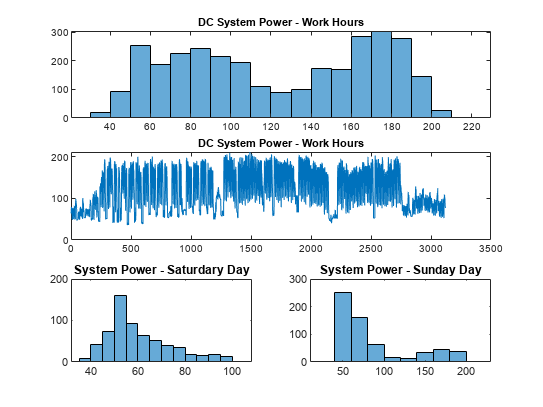


figure
subplot(3,2,[1 2])
histogram(DCWrkHrs)
title("DC System Power - Work Hours")
subplot(3,2,[3 4])
plot(DCWrkHrs)
title("DC System Power - Work Hours")
subplot(3,2,5)
histogram(DCSaturday)
title("System Power - Saturdary Day")
subplot(3,2,6)
histogram(DCSunday)
title("System Power - Sunday Day")

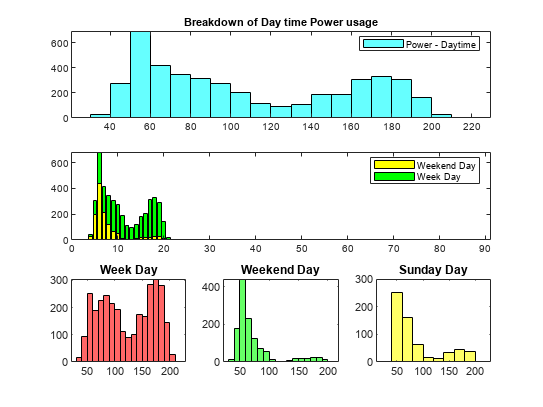




% figure
% histogram(DCDayTime,"FaceColor","c")
% hold on 
% histogram(DCWrkHrs, "FaceColor","r")
% histogram(DCSaturday,"FaceColor","g")
% histogram(DCSunday, "FaceColor", "y")
% hold off
% legend("Day Power", "Week Day", "Saturday","Sunday")

figure 
binrng = 1:10:900;
constDayTimeDC    = histc(DCDayTime,binrng);
constWrkHrsDC     = histc(DCWrkHrs,binrng);
constSatDC        = histc(DCSaturday,binrng);
constSunDC        = histc(DCSunday,binrng);
constWeekendDayDC = histc(DCWeekendDay,binrng);
dayBreakDownDC = [constWeekendDayDC,constWrkHrsDC];

subplot(3,3,[1 2 3])
histogram(DCDayTime, "FaceColor","c")
title("Breakdown of Day time Power usage")
legend("Power - Daytime")

subplot(3,3,[4 5 6])
bDC = bar(dayBreakDownDC,"stacked");
%bDC(3).FaceColor = "red";
bDC(2).FaceColor = "green";
bDC(1).FaceColor = "y";
legend( "Weekend Day","Week Day")

subplot(3,3,7)
histogram(DCWrkHrs, "FaceColor","r")
title("Week Day")
subplot(3,3,8)
histogram(DCWeekendDay, "FaceColor","g")
title("Weekend Day")
subplot(3,3,9)
histogram(DCSunday, "FaceColor","y")
title("Sunday Day")

**Avg Daily Load**

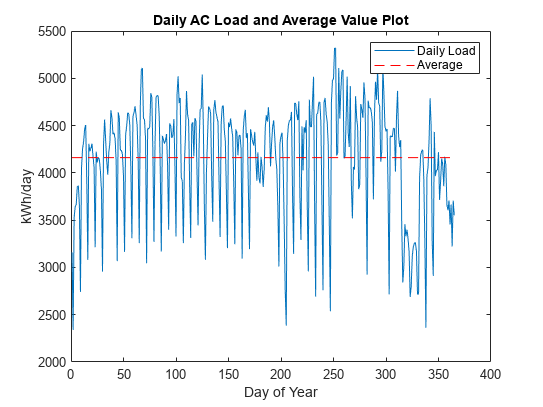


SumPerDay = varfun(@sum, data, "GroupingVariables","date");
AvgDailyLoad = mean(SumPerDay.sum_ptot);
figure
plot(SumPerDay.date,SumPerDay.sum_ptot)
hold on
plot(repmat(AvgDailyLoad,365) , 'r--'); % Change 'r--' to customize the line style

% Customize your plot (add labels, title, legend, etc.) as needed
xlabel('Day of Year');
ylabel('kWh/day');
title('Daily AC Load and Average Value Plot');
legend('Daily Load', 'Average');
hold off

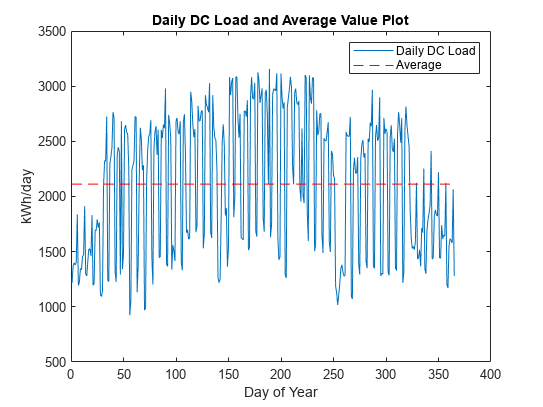




AvgDailyDCLoad = mean(SumPerDay.sum_DC);

figure
plot(SumPerDay.date,SumPerDay.sum_DC)
hold on
plot(repmat(AvgDailyDCLoad,365) , 'r--'); % Change 'r--' to customize the line style

% Customize your plot (add labels, title, legend, etc.) as needed
xlabel('Day of Year');
ylabel('kWh/day');
title('Daily DC Load and Average Value Plot');
legend('Daily DC Load', 'Average');
hold off

AvgPerHour = varfun(@mean, data, "GroupingVariables","time");
% 
% bar(AvgPerHour.mean_tou_id)
% title("3-OffPeak, 2-Standard, 4-Peak")
% xlabel("hour of the day")






%Caluculating average Reading PerDay
AvgPerDay = varfun(@mean, data,"GroupingVariables","date");


avgPerDay_Interp = interp1(AvgPerDay.mean_ptot,data.date);



AvgPerDayWeek = varfun(@mean, data, "GroupingVariables","day");

PeakPerDayWeek = varfun(@max , data, "GroupingVariables", "day");

peakDay = max(PeakPerDayWeek.max_ptot);
AvgDay = mean(AvgPerDayWeek.mean_ptot)*24

AvgDay = 4.1626e+03

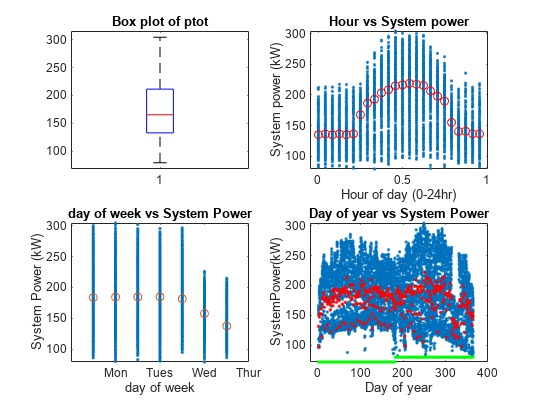


figure
subplot(2,2,1)
boxplot(data.ptot)
title("Box plot of ptot")

subplot(2,2,2)
gscatter(data.time,data.ptot)
title("Hour vs System power")
ylabel("System power (kW)")
xlabel("Hour of day (0-24hr)")
hold on 
scatter(AvgPerHour.time, AvgPerHour.mean_ptot, "red")
hold off

subplot(2,2,3)
gscatter(data.day, data.ptot)
title("day of week vs System Power")
ylabel("System Power (kW)")
xlabel("day of week")
xticklabels(["","Mon","Tues", "Wed", "Thur", "Fri", "Sat", "Sun"])
hold on
scatter(AvgPerDayWeek.day, AvgPerDayWeek.mean_ptot )
hold off

subplot(2,2,4)
gscatter(data.date, data.ptot)
hold on
scatter(AvgPerDay.date,AvgPerDay.mean_ptot,"red",".")
scatter(AvgPerDay.date, AvgPerDay.mean_season_profile_id , "green",".")
hold off
title("Day of year vs System Power") %average per day data and show one point per day (or show peak per day)
ylabel("SystemPower(kW)")
xlabel("Day of year")

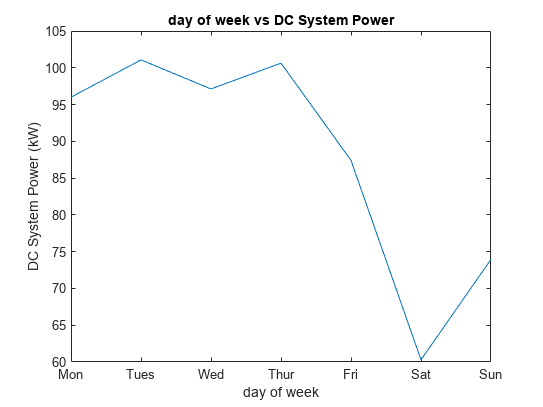

figure

plot(AvgPerDayWeek.day, AvgPerDayWeek.mean_DC)
title("day of week vs DC System Power")
ylabel("DC System Power (kW)")
xlabel("day of week")
xticklabels(["Mon","Tues", "Wed", "Thur", "Fri", "Sat", "Sun"])
hold on

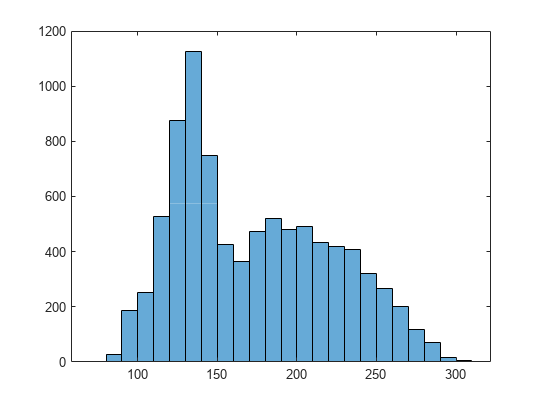

figure
histogram(data.ptot) %bimodal, intersetting - sepertate working hours vs off hours to look at each peak

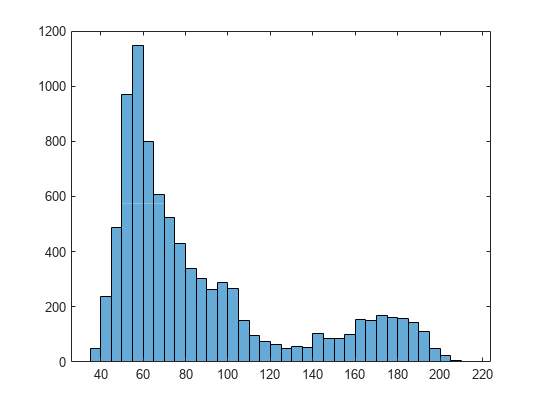

histogram(data.DC)

%figure what the fuck is going on below 100
%idxLowPower = 



% figure
% 
% X = [data.date,data.tstamp,data.day,data.ptot];
% varNames = {'Day of Year'; 'Time of Day'; 'Day of Week'; 'System True Power'};
% 
% gplotmatrix(X);
% text([.08 .24 .43 .66 ], repmat(-.1,1,4), varNames, 'FontSize',8);
% text(repmat(-.12,1,4), [.86 .62 .41 .25 ], varNames, 'FontSize',8, 'Rotation',90);

### Dimensionality Reduction

%Try PCA

PCA

% pcaArray = data(:,1:end-1);
% pcaArray = table2array(pcaArray);
% 
% [pcs,scrs,~,~,pctExp] = pca(pcaArray);
% figure
% pareto(pctExp)
% title("Pareto chart of principal components")
% 
% varnames= data.Properties.VariableNames;
%  heatmap(abs(pcs(:,1:7)),...
%      "YDisplayLabels",varnames(1:end-1));
%  xlabel("Principal Component")
% 
% 


Sequential Feature Analysis

%ferror = @(XTrain,yTrain,XTest,yTest) nnz(yTest ~= predict(fitctree(XTrain,yTrain),XTest));

%toKeep = sequentialfs(ferror,data{:,1:end-1},data.futPtot)


### Anomaly Detection

%Can use statistical methods to find outliers

%Can try use some ML ting


MORE EDA

stratification (Strata)

- seperate data into strata

- ptot by day/month/season

- boxplots slap

#### Fucken around and trying some shit

[https://www.mathworks.com/help/deeplearning/ug/time-series-forecasting-using-deep-learning.html](https://www.mathworks.com/help/deeplearning/ug/time-series-forecasting-using-deep-learning.html) Useful shit for 

predicting future timeseries values.

%removing casue fitrsvm doesn't like them

% 
% numObs = height(data);
% percentSplit = 0.8;
% idxTrain = 1:floor(percentSplit*numObs);                                
% idxTest = floor(percentSplit*numObs)+1:numObs; 
% dataTrain = data(idxTrain,:);
% dataTest = data(idxTest,:);   

%mdl = fitrsvm(dataTrain,"ptot","Standardize",true, "KernelFunction","polynomial");
% mdl = fitrnet(dataTrain, "ptot","Standardize",true)
% mdlLoss = loss(mdl, dataTest)
% ptotPred = predict(mdl, dataTest);
% 
% figure
% plot(dataTest.ptot)
% hold on
% plot(ptotPred)
% hold off
% legend("ActualPower" , "PredPower")
%evaluateFit(dataTest.ptot, ptotPred, "SVM")

